# Rocky Balance Base System

## Nabih Estefan and Olivia Jo Bradley

clear all
addpath("data/");

**Determine tau and K**

syms s K_sys tau
desiredVel300 = 1;

values300 = load('actualVel300.mat').actualVel300;
final = 80;

Vin = 300;

leftV = values300(1:80,1);
rightV = values300(1:80,2);
time = values300(1:80,3)/1000;
time = time - time(1);

Ms = ((K_sys/tau) / (s + 1/tau)) * Vin/s; %for final value theroem
Mt = ilaplace(Ms)

$$Mt = 300\,K_{\mathrm{sys}}-300\,K_{\mathrm{sys}}\,{\mathrm{e}}^{-\frac{t}{\tau }}$$

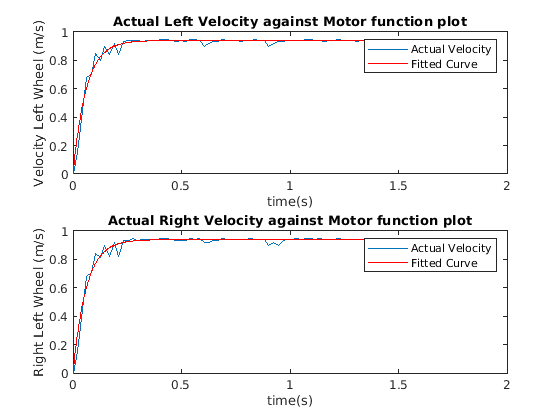


fittypeLeft = fittype(char(Mt), 'independent', 't');
fLeft = fit(time, leftV, fittypeLeft, 'Start', [time(2), leftV(2)]);
fRight = fit(time, rightV, fittypeLeft, 'Start', [time(5), rightV(5)]);

figure()
subplot(2,1,1)
plot(time, leftV)
hold on
plot(fLeft)
title('Actual Left Velocity against Motor function plot')
xlabel('time(s)')
ylabel('Velocity Left Wheel (m/s)')
legend('Actual Velocity', 'Fitted Curve')
hold off

subplot(2,1,2)
plot(time, rightV)
hold on
plot(fRight)
title('Actual Right Velocity against Motor function plot')
xlabel('time(s)')
ylabel('Right Left Wheel (m/s)')
legend('Actual Velocity', 'Fitted Curve')
hold off


tauL = fLeft.tau;
kL = fLeft.K_sys;
tauR = fRight.tau;
kR = fRight.K_sys;

tau = (tauL + tauR)/2 % 16.5993

tau = 0.0602

K_Sys = (kL + kR)/2 % 0.0031

K_Sys = 0.0031

**Determining the natural frequency and effective length**

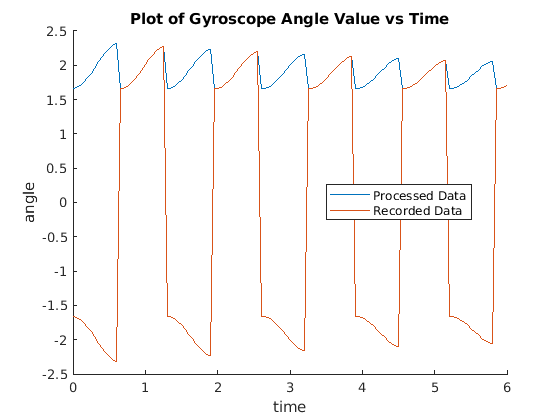

load('natFreqData.mat')
absNatFreqData = abs(natFreqData); % not abs valued
timeForFreq = linspace(0,6,length(absNatFreqData))';

figure()
hold on
plot(timeForFreq, absNatFreqData)
plot(timeForFreq, natFreqData)
hold off
title("Plot of Gyroscope Angle Value vs Time")
xlabel('time'); ylabel('angle')
legend("Processed Data", "Recorded Data", "location", "best")



t = timeForFreq; %0:.001:1-0.001;
Fs = 20; %1e3;
x = absNatFreqData;
x = detrend(x,0);
xdft = fft(x);
freq = 0:Fs/length(x):Fs/2;
xdft = xdft(1:length(x)/2+1);

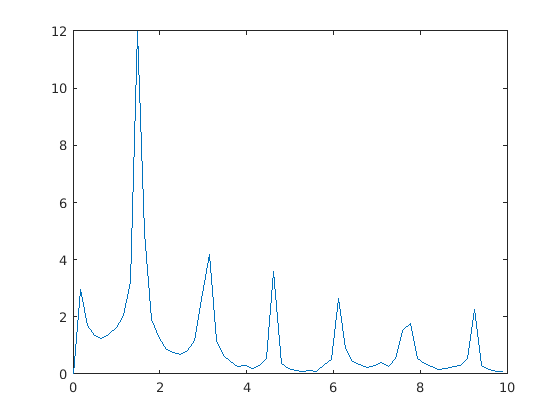


figure()
plot(freq,abs(xdft));


[~,I] = max(abs(xdft));
fprintf('Maximum occurs at %d Hz.\n',freq(I));

Maximum occurs at 1.487603e+00 Hz.



wn = freq(I) * 2 * pi

wn = 9.3469

g = 9.81; % m/s
leff = 0.5588 - g/(wn^2)% in meters

leff = 0.4465

**Performance Specifications**

We are planning to create a slightly underdamped system. We want dampening values (zeta) of around .90 and .85. We have two values because it is a fifth degree equation, so we are separating it into two values for more stability. This means we have a high decay of angles and a frequency of oscillations relatively close to the natural frequency. The disturbance we are working against is any type of push towards the rocky, specifically pushes that change his angle of tilt but do not turn him. This could theoretically be represented as a consant step input with boundaries in the time domain.

**Identify locations for the poles of our system**

syms s a b L g Kp Ki Jp Ji Ci           % define symbolic variables

Hv = -s/L/(s^2-g/L);                    % TF from velocity to angle of pendulum
K = Kp + Ki/s;                          % TF of the angle controller
J = Jp + Ji/s + Ci/s^2;                 % TF of the controller around the motor
M = a*b/(s+a);                          % TF of motor
Md = M/(1+M*J);                         % TF of motor + feedback controller around it 
                                        % J is applied on the feedback path

% pretty(collect(Md)) % display Md(s)

Htot = 1/(1-Hv*Md*K);                    % this is the total transfer function from disturbance d(t) to \theta(t)

(simplify(Htot)) % display the total transfer function

$$ans = -\frac{1}{\frac{a\,b\,s^{2}\,\left(\mathrm{Ki}+\mathrm{Kp}\,s\right)}{\left(g-L\,s^{2}\right)\,\left(a\,s^{2}+s^{3}+\text{Ci}\,a\,b+\mathrm{Jp}\,a\,b\,s^{2}+\mathrm{Ji}\,a\,b\,s\right)}-1}$$


% Substitute parameters and solve

% system parameters
g = 9.81;                               % gravitational acceleration
L = leff;                                % motor time constant
a = 1/tau;
b = K_Sys;

Htot_subbed = subs(Htot);               % substitutes parameters defined above into Htot


**Kp and Ki values that meet our specifications**

% define the target poles
angle1 = 25;
angle2 = 30;

p1 = wn*(-cosd(angle1) + sind(angle1))

p1 = -4.5210

p2 = wn*(-cosd(angle1) - sind(angle1))

p2 = -12.4213

p3 = -wn

p3 = -9.3469

p4 = wn*(-cosd(angle2) + sind(angle2))

p4 = -3.4212

p5 = wn*(-cosd(angle2) - sind(angle2))

p5 = -12.7681


% this is the target characteristic polynomial
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5);

% get the denominator from Htot_subbed
[num, den] = numden(Htot_subbed);

% find the coefficients of the denominator polynomial TF
cDenom = coeffs(den, s);

% divide out the coefficient of the highest power term
cDenom = coeffs(den, s)/(cDenom(end));

% find coefficients of the target charecteristic polynomial
cTarget = coeffs(tgt_char_poly, s);

% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(cDenom == cTarget, Jp, Ji, Kp, Ki, Ci);

% display the solutions as double precision numbers

Jp = double(solutions.Jp)

Jp = 497.7807

Ji = double(solutions.Ji)

Ji = -1.5643e+04

Kp = double(solutions.Kp)

Kp = 1.3046e+04

Ki = double(solutions.Ki)

Ki = 6.1176e+04

Ci = double(solutions.Ci)

Ci = -2.0073e+04

   
TF = char(subs(Htot));
% Define 's' as transfer function variable    
s = tf('s');        
eval(['TFH = ',TF]);    

TFH =
 
  2.466e96 s^8 + 1.457e98 s^7 - 3.21e98 s^6 - 3.907e100 s^5 - 3.686e100 s^4 + 7.88e101 s^3 + 9.386e101 s^2
  ---------------------------------------------------------------------------------------------------------
  2.466e96 s^8 + 1.457e98 s^7 + 3.425e99 s^6 + 4.068e100 s^5 + 2.547e101 s^4 + 7.88e101 s^3 + 9.386e101 s^2
 
Continuous-time transfer function.



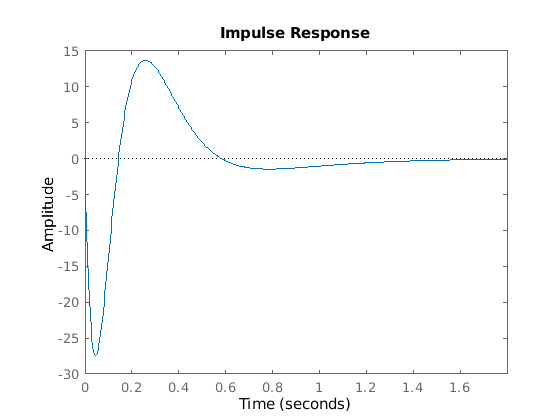

figure()
impulse(TFH);

**x(t) and v(t) responses**

words

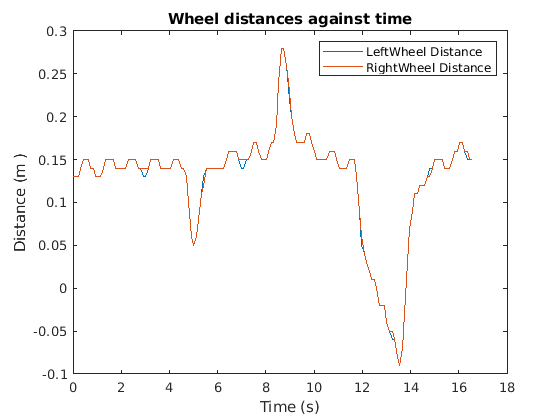

load('rockyNormalData.mat');
time = rockyNormalData(:,1);
time = time - time(1);
time = time /1000;
distLeft = rockyNormalData(:,2);
distRight = rockyNormalData(:,3);
velLeft = rockyNormalData(:,4);
velRight = rockyNormalData(:,5);

figure()
plot(time, distLeft)
hold on
plot(time, distRight)
legend('LeftWheel Distance', 'RightWheel Distance')
title("Wheel distances against time")
xlabel("Time (s)")
ylabel("Distance (m )")
hold off

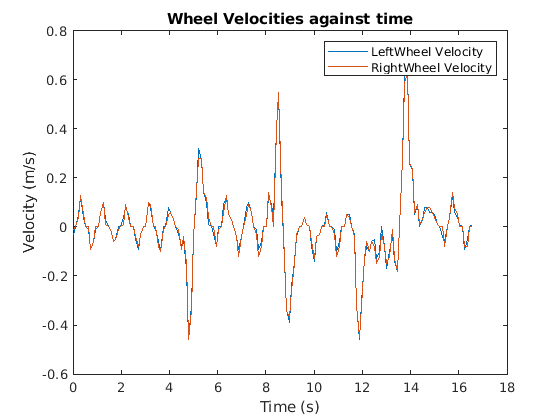


figure()
plot(time, velLeft)
hold on
plot(time, velRight)
legend('LeftWheel Velocity', 'RightWheel Velocity')
title("Wheel Velocities against time")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
hold off

In the graphs above, you can see the distance and velocities of the wheels in a normal run. You can also see the external inputs we gave the Rocky robot at times t = 5, 9, and 12, with the one at t = 12 being a much bigger than the other two. Besides, you can also see how the velocity reacts to the pushes to get the rocky to return to its original spot.